Databas hantering

% INNAN IMPLEMENTATION ETC

% Minska antalet bilder i databasen genom att jämföra bilderna mot varandra
% med de bilder som bäst täcker färgrymden. Till ca 50 eller 100 bilder.

% lägg till filväg till alla bilder
addpath('databas')

Att göra: filtrera fram de bästa av t.ex. 1000 bilder så att de återstår 200 bilder kmeans kan användas som exempel för att avgöra vilka de 200 bästa kandidater är.

Glöm ej att ändra storlek på alla bilder oxå. till ca 20x20 eller 25x25

Beräkna oxå fram ett LAB värde till alla bilder som senare kan användas för jämföring MED DELTA E

% Create database matrix
database = cell(1,40);

for i = 1:size(database,2)
    fileName = strcat(int2str(i),'.jpg');
    img = im2double(imread(fileName));
    database{i} = img;
end

Implementation


% Ladda in orginalbild

% Skala om orginalbild till önskad storlek

% Om bilden är för liten, ska den skalas upp och ge ett meddelande om
% detta. Och vad det har för konsekvenser


% SNR - jämföra bild från databas med "bild" från orginalbild
% där "bild" är 10x10 av orginalbilden

TEST

% img = im2double(imread('garen.png')); %256x256
% 
% % rgb till lab
% 
% imgLAB = rgb2lab(double(img));
% 
% imshow(lab2rgb(imgLAB))
% 
% % create cells from the original img
% 
% imgTiles = mat2tiles(imgLAB, [16,16]);
% 
% imshow(lab2rgb(cell2mat(imgTiles(8,8))))
% 
% % using the little part
% 
% imgCell = cell2mat(imgTiles(8,8));
% 
% %Create reference image
% imgREF1 = im2double(imread('0.jpg'));
% imgREF1 = imresize(imgREF1,[16,16]);
% imgREFLAB1 = rgb2lab(imgREF1);
% 
% imgREF2 = im2double(imread('1.jpg'));
% imgREF2 = imresize(imgREF2,[16,16]);
% imgREFLAB2 = rgb2lab(imgREF2);
% 
% imgREF3 = im2double(imread('2.jpg'));
% imgREF3 = imresize(imgREF3,[16,16]);
% imshow(imgREF3)
% imgREFLAB3 = rgb2lab(imgREF3);
% 
% % [A1, ssimD1] = ssim(imgCell, imgREFLAB1);
% % [A2, ssimD2] = ssim(imgCell, imgREFLAB2);
% % [A3, ssimD3] = ssim(imgCell, imgREFLAB3);
% 
% 
% % CODE
% 
% image = zeros(256,256,3);
% siz = size(image)/16
% siz = int16(siz(1))

% Old for-loop only using 2 ref images
% for i = 1:16
%     for j = 1:16
%         %imgCellMatrix(:,:,:) = cell2mat(imgTiles(i,j));
%         [A, ssim1] = ssim(cell2mat(imgTiles(i,j)), imgREFLAB2);
%         [A2, ssim2] = ssim(cell2mat(imgTiles(i,j)), imgREFLAB3);
%         
%         if(A > A2)
%             image(i*siz - siz+1 : i*siz, j*siz - siz+1 : j*siz,:) = imgREFLAB2;
%         else
%             image(i*siz - siz+1 : i*siz, j*siz - siz+1 : j*siz,:) = imgREFLAB3;
%         end
%     end
% end
% imshow(lab2rgb(image))

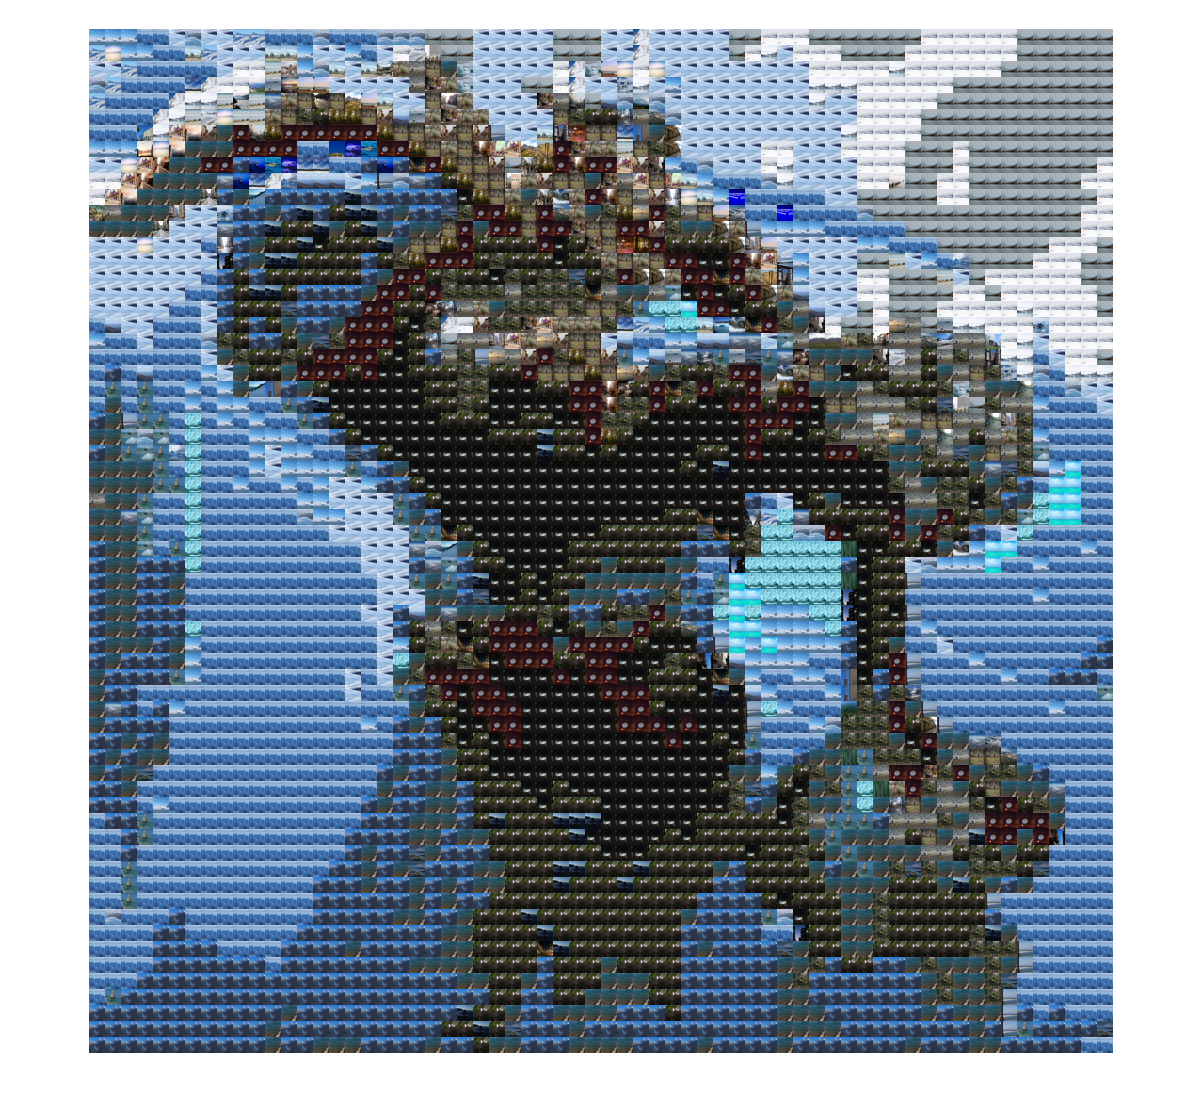

    %New code that uses database TRIPLE NESTED

% Load in image of sexy Garen 512x512 MUST BE QUADRATIC AT THE MOMENT
% helst delbar på 16
img = im2double(imread('godgaren.jfif'));

% the size of the sectioning of the image
smallCellSize = 8;

% number of optimal images from deltaE
n = 10;

% rgb till lab
img = rgb2lab(double(img));
    
% create cells from the original img
imgTiles = mat2tiles(img, [smallCellSize,smallCellSize]);

imageOUT = zeros(size(img,1)*2,size(img,1)*2,3);

% går att göra dessa två rader finare
siz = smallCellSize*2;
siz = int16(siz(1));

imgREF = zeros(smallCellSize,smallCellSize,3);


% Matrix for holding the best candidates from database
imgDE = cell(1,3);



% for-loop for each "small cell" to create the image of small images
for i = 1:size(img,1)/smallCellSize
    for j = 1:size(img,1)/smallCellSize
        
        %Create cell image from original image
        imageMatrix = cell2mat(imgTiles(i,j));
        
        % Matrix for holding all deltaE values
        dE = zeros(1,200);
        
        for k = 1:size(smallDatabase,2)
            % Temporary image created from database
            imgTEMP = cell2mat(smallDatabase(k));
            imgTEMP = imresize(imgTEMP,[smallCellSize,smallCellSize]);
            imgTEMP = rgb2lab(imgTEMP);
            
            % calculating delta E values for all images
            dE(1,k) = mean(mean(sqrt( (imgTEMP(:,:,1) - imageMatrix(:,:,1)).^2 + (imgTEMP(:,:,2) - imageMatrix(:,:,2)).^2 + (imgTEMP(:,:,3) - imageMatrix(:,:,3)).^2)));
        end
                        
        % array for the 'n' best values
        val = zeros(n,1);
        dEtemp = dE;
        for k=1:n
          [val(k),idx] = min(dEtemp);
          % remove for the next iteration the last smallest value: (maybe not needed)
          dEtemp(idx) = [];
        end
        
        bestMatches = cell(1,n);
        % find the positions of the images containing the best values
        for k=1:n
            [row, col] = find(abs(dE-val(k))<1e-3);

            for h = 1:size(col,2)
                bestMatches(k+h-1) = smallDatabase(col(1,h));    
            end
        end
                
        ref = 0;
        for k = 1:size(bestMatches,2)
            tinyRef = imresize(cell2mat(bestMatches(k)), [smallCellSize*2, smallCellSize*2]);
            [value, outImage] = ssim(imresize(lab2rgb(imageMatrix), 2), tinyRef);
                         
            if(value > ref)
                ref = value;
                imgREF = tinyRef;
            end
        end
        
        
        % Add to image
        imageOUT(i*siz - siz+1 : i*siz, j*siz - siz+1 : j*siz,:) = imgREF;

    end
end

imshow((imageOUT))

% % new version without tripple nested for-loop
% 
% % Load in image of sexy Garen 512x512 MUST BE QUADRATIC AT THE MOMENT
% % helst delbar på 16
% img = im2double(imread('godgaren.jfif'));
% smallCellSize = 8;
%     
% % rgb till lab
% imgLAB = rgb2lab(double(img));
%     
% % create cells from the original img
% imgTiles = mat2tiles(imgLAB, [smallCellSize,smallCellSize]);
% 
% 
%     
% % convert matrix to 1 dimension
% imgTiles = imgTiles(:);
% 
% % create a image
% image = zeros(size(img,1),size(img,1),3);
% % turn into 1 dimensional image
% %image = image(:);
% siz = smallCellSize;
% siz = int16(siz(1));
% % create ref image
% imgREF = zeros(smallCellSize,smallCellSize,3);
% for i = 1:size(imgTiles,1)
%     % create and reset the value of ref
%     ref = 0;
%     imageMatrix = cell2mat(imgTiles(i));
%     for k = 1:size(smallDatabase,2)
%         % Temporary image created from database
%         imgTEMP = cell2mat(smallDatabase(k));
%         imgTEMP = imresize(imgTEMP,[smallCellSize,smallCellSize]);
%         imgTEMP = rgb2lab(imgTEMP);
%            
%         % Compare TEMP image to "cell" from original image
%         [value, outImage] = ssim(imageMatrix, imgTEMP);
%         
%         if(value > ref)
%             ref = value;
%             imgREF = imgTEMP;
%         end
%     end
%     
%     image(i*siz - siz+1:i*siz,i*siz - siz+1:i*siz,:) = imgREF;
% end
% 
% % put together the row image to a normal image
% finalImage = reshape(image, [], 64);
% 
% imshow(cell2mat(finalImage))
% 
% 


